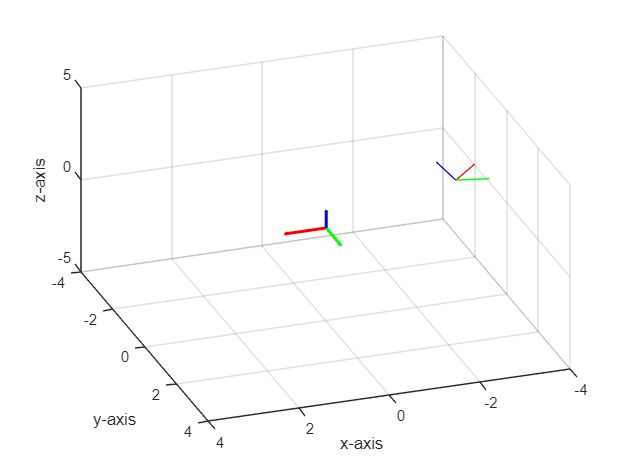

% Table of Contents
% INPUTS
% General motion transformation by Kai De La Cruz - 1/25/25
% PURPOSE:
% Capable of three consecutive transforms from frame B (noa) and finds
% new representation in frame B.
% Furthermore, translates representation in noa frame to the fixed
% reference frame if frame B was originally attached at origin and parallel.

% INPUTS
% Original point in frame B
xxx = 2;
yyy = -1;
zzz = 3;

% Translation
x = -2;
y = 4;
z = 1;

% Define the rotation angles (in degrees)
theta_x = 30; % Rotation about the X-axis
theta_y = 0; % Rotation about the Y-axis
theta_z = 45; % Rotation about the Z-axis

function T = T_translation(dx, dy, dz)
    T = [1 0 0 dx; 
         0 1 0 dy; 
         0 0 1 dz; 
         0 0 0 1];
end

function [T, theta_xx, theta_yy, theta_zz] = rot(axis, angle)
    theta_xx = 0; 
    theta_yy = 0; 
    theta_zz = 0; 

    if axis == "x"
        T = [1 0 0 0; 
             0 cosd(angle) -sind(angle) 0; 
             0 sind(angle) cosd(angle) 0; 
             0 0 0 1];
        theta_xx = angle;
    elseif axis == "y"
        T = [cosd(angle) 0 sind(angle) 0; 
             0 1 0 0; 
             -sind(angle) 0 cosd(angle) 0; 
             0 0 0 1];
        theta_yy = angle;
    else
        T = [cosd(angle) -sind(angle) 0 0; 
             sind(angle) cosd(angle) 0 0; 
             0 0 1 0; 
             0 0 0 1];
        theta_zz = angle;
    end
end

function [F_new] = transform(T_XX, F_old, relation)
    if strcmp(relation, "fixed")
        F_new = T_XX * F_old;
    elseif strcmp(relation, "ref")
        F_new = F_old * T_XX;
    end
end

function PlotRotatingAxes(T_new)
    quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 1), T_new(2, 1), T_new(3, 1), 'r');
    hold on;
    quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 2), T_new(2, 2), T_new(3, 2), 'g');
    quiver3(T_new(1, 4), T_new(2, 4), T_new(3, 4), T_new(1, 3), T_new(2, 3), T_new(3, 3), 'b');
    hold off;
    xlabel('x-axis');
    ylabel('y-axis');
    zlabel('z-axis');
    view([160.69 40.76]);
    grid on;
    xlim([-4, 4]);
    ylim([-4, 4]);
    zlim([-5, 5]);  
end

function PlotFixedAxes()
    % figure(FigNum);
    hold on
    quiver3(0, 0, 0, 1, 0, 0, 'r', 'LineWidth', 2);
    quiver3(0, 0, 0, 0, 1, 0, 'g', 'LineWidth', 2);
    quiver3(0, 0, 0, 0, 0, 1, 'b', 'LineWidth', 2);
    grid on;
end

% Common rotation transforms
identity = [1 0 0 0; 
            0 1 0 0; 
            0 0 1 0; 
            0 0 0 1];

% 3 Consecutive Transforms Calculation
P_0 = [-1 0 0 xxx; 
       0 1 0 yyy; 
       0 0 1 zzz; 
       0 0 0 1]; % Original point in frame B, at [2,3,4] transposed

% Transform 1 plot
for n=1:1
    for i=0:10
        T_01 = T_translation(x*i/10, y*i/10, z*i/10); % First transform, [-2,4,1]T about fixed frame
        P_1 = transform(T_01, P_0, "fixed");
        hold off
        figure(1)
        PlotRotatingAxes(P_1);
        hold on
        PlotFixedAxes()
        pause(0.2)
    end
    for i=0:10
        % Transform 2 plot
        T_12 = rot("z", theta_z*i/10); % Second transform, rotation about z by 45 degrees
        P_2 = transform(T_12, P_1, "fixed");
        hold off
        PlotRotatingAxes(P_2);
        hold on;
        PlotFixedAxes()
        pause(0.2)
    end
    for i=0:10
        % Transform 3 plot
        T_23 = rot("x", theta_x*i/10); % Third transform, rotation about x by 30 degrees
        P_3 = transform(T_23, P_2, "ref");
        hold off
        PlotRotatingAxes(P_3);
        hold on;
        PlotFixedAxes()
        pause(0.2)
    end
end